## Simulate 3 species mCRPC model with Abiraterone treatment.

### 1. Initial conditions

We need to have initial conditions of ESS population densities. We can run the ESS Analysis file, but the faster way is to use the hard coded results since it will be musch faster. 

% ESSAnalysis; (run ESSAnalysis file will be slow), so we use the hard coded result as we already knew it.

ESS = [3196.34703196346,7077.62557077625,2739.72602739727,26027.3972602740;5607.47663551401,7476.63551401869,467.289719626177,27102.8037383178;1.e-09,4545.45454545455,6818.18181818182,22727.2727272727;2786.37770897833,6501.54798761610,3405.57275541796,25386.9969040248;6270.62706270627,7260.72607260726,330.033003300335,27722.7722772277;5140.18691588785,7476.63551401869,934.579439252341,27102.8037383178;6060.60606060606,7575.75757575758,1.e-09,27272.7272727273;6617.64705882353,7352.94117647059,1.e-09,27941.1764705882;6617.64705882353,7352.94117647059,1.e-09,27941.1764705882;6617.64705882353,7352.94117647059,1.e-09,27941.1764705882;1.e-09,4545.45454545455,6818.18181818182,22727.2727272727;7141.90425687459,7142.65465924746,0.833764523678801,28570.7853484204;7142.85714285714,7142.85714285714,1.e-09,28571.4285714286;7142.85714285714,7142.85714285714,1.e-09,28571.4285714286;7142.85714285714,7142.85714285714,1.e-09,28571.4285714286;7142.85714285714,7142.85714285714,1.e-09,28571.4285714286;1.e-09,4545.45454545455,6818.18181818182,22727.2727272727;4310.34482758620,6034.48275862069,2586.20689655173,25862.0689655172;7096.77419354839,6451.61290322581,1.e-09,27096.7741935484;7096.77419354839,6451.61290322581,1.e-09,27096.7741935484;7096.77419354839,6451.61290322581,1.e-09,27096.7741935484;7096.77419354839,6451.61290322581,1.e-09,27096.7741935484];
matrixCoefficients = [0.7,0.9,0.4,0.6,0.5,0.8;0.7,0.8,0.4,0.6,0.5,0.9;0.6,0.9,0.4,0.8,0.5,0.7;0.6,0.9,0.4,0.7,0.5,0.8;0.6,0.8,0.4,0.7,0.5,0.9;0.7,0.9,0.4,0.5,0.6,0.8;0.7,0.8,0.4,0.5,0.6,0.9;0.6,0.9,0.4,0.5,0.7,0.8;0.6,0.8,0.4,0.5,0.7,0.9;0.6,0.7,0.4,0.5,0.8,0.9;0.5,0.9,0.4,0.8,0.6,0.7;0.5,0.9,0.4,0.7,0.6,0.8;0.5,0.8,0.4,0.7,0.6,0.9;0.5,0.9,0.4,0.6,0.7,0.8;0.5,0.8,0.4,0.6,0.7,0.9;0.5,0.7,0.4,0.6,0.8,0.9;0.4,0.9,0.5,0.8,0.6,0.7;0.4,0.9,0.5,0.7,0.6,0.8;0.4,0.8,0.5,0.7,0.6,0.9;0.4,0.9,0.5,0.6,0.7,0.8;0.4,0.8,0.5,0.6,0.7,0.9;0.4,0.7,0.5,0.6,0.8,0.9];

### 2. Choose a patient to work with by choosing matrixIndex

choose patient 1 when you set matrixIndex = 7; choose patient 2 when you set matrixIndex = 5

Now we work with patient 2 first, later if we want to work with patient 1, we need to change the matrixIndex here.

matrixIndex = 5;

## 3. Choose Abiraterone treatment strategy by uncommenting one of the following

% treatmentType = 'None';
% treatmentType = 'SOC';
% treatmentType = 'Metronomic';
treatmentType = 'Adaptive';

## 4. Set up parameters

% Get all competition coefficients.
alphas = matrixCoefficients(matrixIndex,:);

% set growth rates
scale = .01;
r = [0.27726, 0.34657, 0.66542];
r = r.*scale;

% set PSA dynamics
sigmaPSA = 0.5;

% Set initial tumor densities at 40% of ESS values
y0 = ESS(matrixIndex, :) .* 0.4;

% Set simulation time as 10000.
maxSimulationTime = 10000;

## 5. Design Treatment

When to give Abiraterone? i.e. at what percentage of ESS PSA?

maxPSAPercent = 0.8;
PSA_zenith = ESS(matrixIndex,4) * maxPSAPercent;
PSA_nadir = PSA_zenith * maxPSAPercent/2;

Find first treatment time to build treatments.

y = y0;
firstTreatmentTime = 0;

while y(4) < PSA_zenith
    
    firstTreatmentTime = firstTreatmentTime + 1;
    
    % Update carrying capacities with current symbiotic T+.
    k = [y(2) * 1.5, 10000, 10000];
    
    % T+, TP, T-, and PSA ODE's
    dydt = zeros(1, 4);
    
    dydt(1) = y(1) * r(1) * (1 - ( ( y(1) + matrixCoefficients(matrixIndex,1) * y(2) + matrixCoefficients(matrixIndex,2) * y(3) ) / k(1) ) );
    dydt(2) = y(2) * r(2) * (1 - ( ( matrixCoefficients(matrixIndex,3) * y(1) + y(2) + matrixCoefficients(matrixIndex,4) * y(3) ) / k(2) ) );
    dydt(3) = y(3) * r(3) * (1 - ( ( matrixCoefficients(matrixIndex,5) * y(1) + matrixCoefficients(matrixIndex,6) * y(2) + y(3) ) / k(3) ) );
    dydt(4) = sum(y(1:3)) - sigmaPSA * y(4);
    
    y = y + dydt;
end


Set Abiraterone flag to 0 means Abiraterone is off. Set Abiraterone flag to 1 means Abiraterone is on. 

Set Abiraterone flag to 0 for the entire simulation when there is no abiraterone treatment (and this is also set to zero out for all other treatment types).

AbiOnOffFlag = zeros(1, maxSimulationTime);


Set Abiraterone flag to 1 after the first treatment time when there is SOC full dose. 

if strcmp(treatmentType, 'SOC')
    AbiOnOffFlag(firstTreatmentTime:maxSimulationTime) = 1;
end


If in Metronomic, gives 800 long induction with cycles thereafter.

if strcmp(treatmentType, 'Metronomic')
    
    % Induction period
    AbiOnOffFlag(firstTreatmentTime:firstTreatmentTime + 800) = 1;
    
    % Cycles start 2000 time units after the first treatment time, are 1000 time units apart, and administer Abiraterone for 200 time units.
    for cycles = 0:1:10
        AbiOnOffFlag(firstTreatmentTime + 2000 + (cycles * 1000):firstTreatmentTime + 2000 + (cycles * 1000) + 200) = 1;
    end
    
    % Clip down to simulation size.
    AbiOnOffFlag = AbiOnOffFlag(1:maxSimulationTime);
end



Adaptive of Abiraterone is built within the following ODE.

## 6. Run the ODE

1) Set the initial state.

y = y0;

2) Create empty matrix for ODE solution and initialize this solution matrix.

allSolution = [];
allSolution(1,:) = y;

3) Run ODE with treatment selection.

for time = 2:maxSimulationTime
    
    % Adaptive Abiraterone is built during the simulation. 
    % Turns Abiraterone on once the PSA zenith value is reached;
    % Turns Abiraterone off once the nadir is reached.
    if strcmp(treatmentType, 'Adaptive')
        if y(4) > PSA_zenith
            AbiOnOffFlag(time) = 1;
        elseif (y(4) < PSA_nadir)
            AbiOnOffFlag(time) = 0;
        else
            AbiOnOffFlag(time) = AbiOnOffFlag(time - 1) ;
        end
    end
    
    % If Abi is being given, then use Abi parameters.
    if (AbiOnOffFlag(time) == 1)
        k = [y(2) * 0.5, 100, 10000];
    
    % If Abi is not being given, use naive parameters.
    elseif AbiOnOffFlag(time) == 0
        k = [y(2) * 1.5, 10000, 10000];
    end
    
    % T+, TP, T-, and PSA ODEs
    dydt = zeros(1, 4);
    
    dydt(1) = y(1) * r(1) * (1 - ( ( y(1) + alphas(1) * y(2) + alphas(2) * y(3) ) / k(1) ) );
    dydt(2) = y(2) * r(2) * (1 - ( ( alphas(3) * y(1) + y(2) + alphas(4) * y(3) ) / k(2) ) );
    dydt(3) = y(3) * r(3) * (1 - ( ( alphas(5) * y(1) + alphas(6) * y(2) + y(3) ) / k(3) ) );
    dydt(4) = sum(y(1:3)) - sigmaPSA * y(4);
    
    y = y + dydt;
        
    % Lower bound check to keep a small density of any cell type.
    y(y<1E-9) = 1E-9;
    
    % Append to solutions vector. 
    allSolution(time, :) = y;
    
end





4) Feature extraction

4-1) Extract when T- frequency reaches 5% and 90% 

TminusFrequency = allSolution(:,3)./( sum(allSolution(:,1:3), 2) ) .* 100;
timeTo5Percent = find(TminusFrequency > 5, 1, 'first');
timeTo90Percent = find(TminusFrequency > 90, 1, 'first');


4-2) Extract percentage of SOC dose

SOCAbi = zeros(1, maxSimulationTime);
SOCAbi(firstTreatmentTime:maxSimulationTime) = 1;
MTDTotalDosage = sum(SOCAbi);
currentTreatmentTotalDosage = sum(AbiOnOffFlag);
%Calculate percentage of MTD
percentageOfSOC = currentTreatmentTotalDosage/MTDTotalDosage * 100;


## 7. Plotting

1) Plot density dynamics

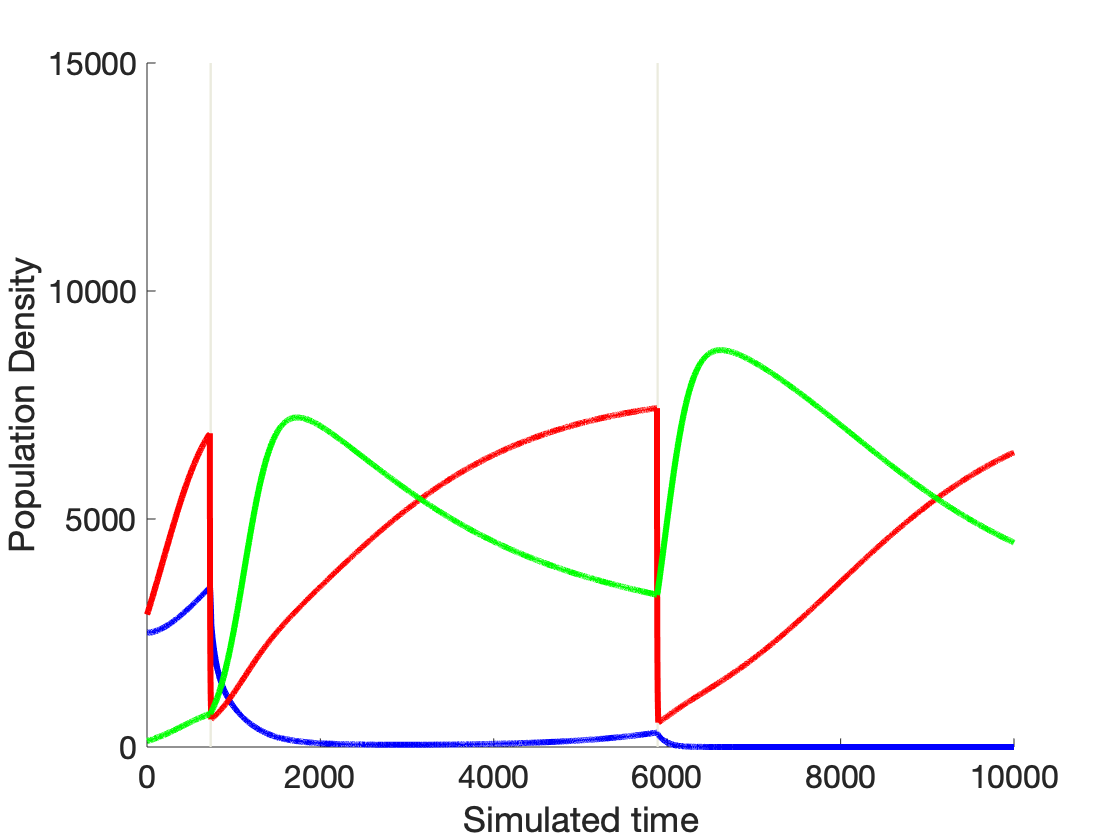

figure('NumberTitle', 'off', 'Name', ['Matrix-', num2str(matrixIndex), ' Densities']);
hold on
% Highlight when Abiraterone is given. - Note that this will be slow. Be patient.
for i = 1:1:length(AbiOnOffFlag)
    if(AbiOnOffFlag(i) == 1)
        X = [i, i];
        Y = [0, AbiOnOffFlag(i) .* 15000];
        plot(X, Y, 'Color', [.92 .92 .87]);
    end
end

% Plot densities.
plot((1:maxSimulationTime), allSolution(:,1), 'b', 'LineWidth', 3, 'DisplayName', 'T+')
plot((1:maxSimulationTime), allSolution(:,2), 'r', 'LineWidth', 3, 'DisplayName', 'TP')
plot((1:maxSimulationTime), allSolution(:,3), 'g', 'LineWidth', 3, 'DisplayName', 'T-')

% Make it pretty.
xlabel('Simulated time')
ylabel('Population Density')
set(gca, 'FontSize', 16)
xlim([0 maxSimulationTime])
ylim([0 15000])

2) Plot PSA dynamics

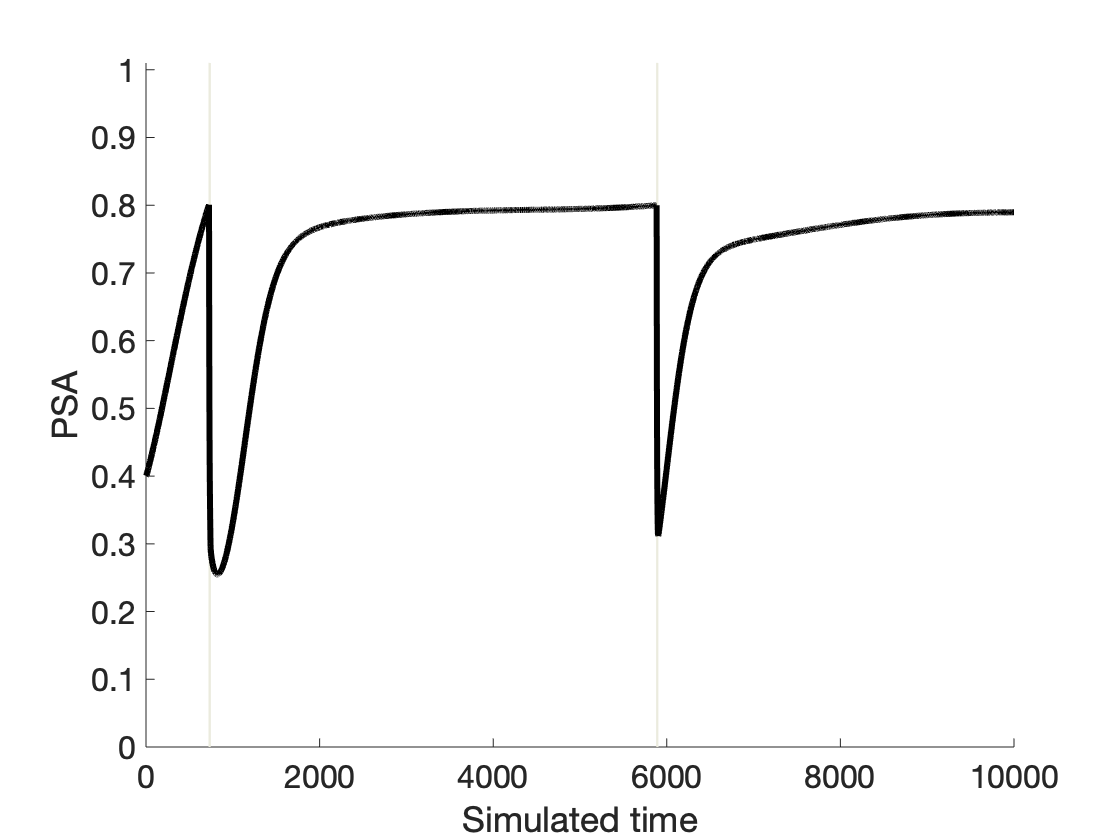

figure('NumberTitle', 'off', 'Name', ['Matrix-', num2str(matrixIndex), ' PSA']);
hold on
% Highlight when Abi is given. - This is slow. Be patient.
for i = 1:1:length(AbiOnOffFlag)
    if(AbiOnOffFlag(i) == 1)
        X = [i, i];
        Y = [0, AbiOnOffFlag(i) .* 15000];
        plot(X, Y, 'Color', [.92 .92 .87]);
    end
end

% Plot PSA scaled to ESS value of PSA
plot((1:maxSimulationTime), allSolution(:,4)./ESS(matrixIndex,4), 'K', 'LineWidth', 3, 'DisplayName', 'PSA')

% Make it pretty.
xlabel('Simulated time')
ylabel('PSA')
set(gca, 'FontSize', 16)
xlim([0 maxSimulationTime])
ylim([0 1.01])